# **Fault Analysis**

**SCHOOL OF ELECTRICAL AND ELECTRONIC ENGINEERING**

**Bachelor of Engineering (Hons) BE in Elect/Cont/Comm/Comp Eng**

**Program Code: (DT021A)**

**<YEAR 4>**

**Name of Module: (Power System Analysis, POWS4601)**

     **Student Name:          __****Talha Tallat, D18124645 ****___**

     **Academic Lecturer:  __*****Jane Courtney*****_______**

     **Submission Date:     __****22nd November 2021____**

**1. Introduction to Fault Analysis **

Fault Analysis helps in exploring the faults that occur in the power networks. Which provides useful data for protection settings and stability expectations. There are various types of faults in the power transmission line that can occur however, four main types of faults occur more often as follows:

- Single line to ground 

- Line to line

- Three-phase to the ground (balanced)

- Line to line to ground

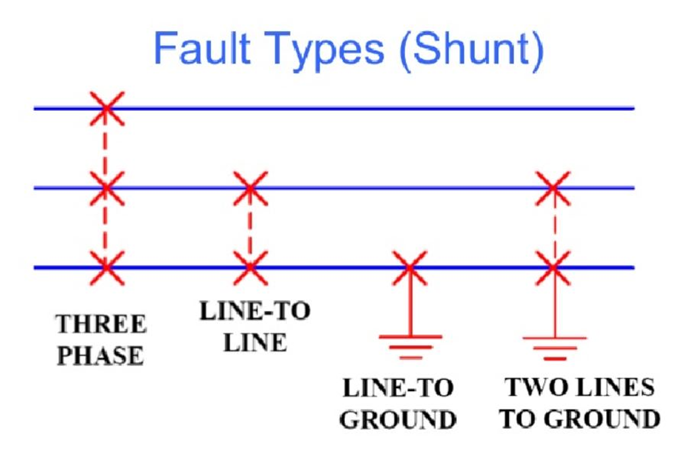

*Figure 1** - Types of faults in power network [1]*

The figure above shows the types of faults, and the most common fault is a Single line to the ground which occurs approximately 75% of the time and a three-phase balanced fault occurs least likely approximately 5% of the time. 

**Assumptions** are also made to simplify the fault analysis:

- At the time fault, the system is operating at no load which means there is no load current so pre-fault currents before the fault are zero. 

- All emf of the generators in the system are operating per unit. Which is   

- Shunt component elements are ignored

- Transient effects are neglected 

**2. Objectives Preparation:**

The purpose of this assignment is to analyze fault in a network where each phase, currents and the phase voltages are effected. The system will be designed in this experiment for solving symmeterical and asymetrical faults at where the faults are occured. The ditribustion system is provided as shown in figure 2 along with a sequence reactances on a 100 MVA base in Table 1 and volatge levels throughout the system shown in KV in Table 2. In the example below fault is occured at bus 3.

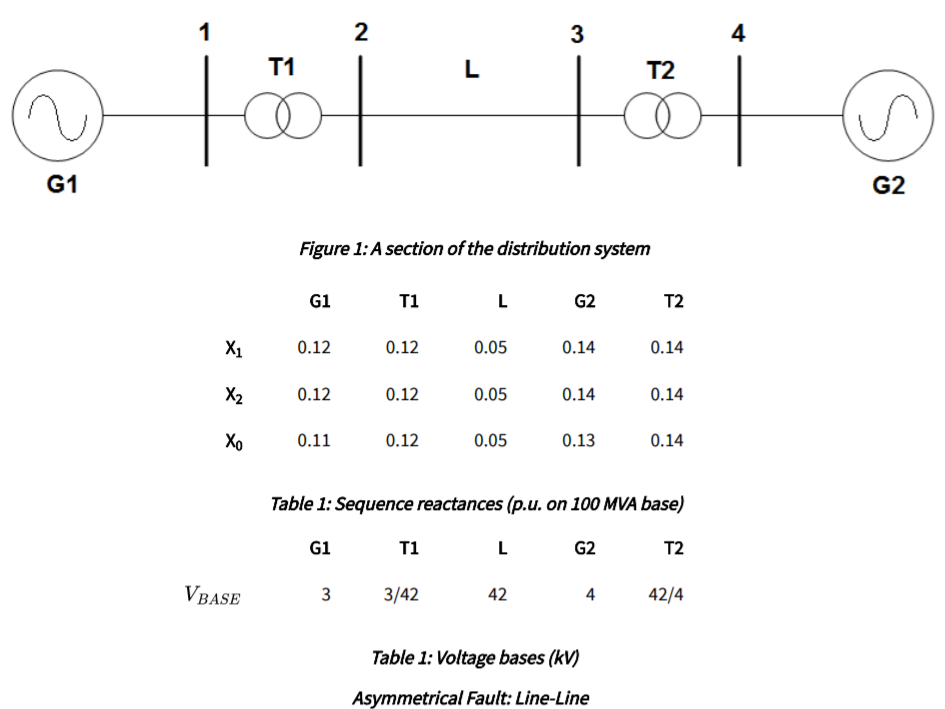

%Inputs are in order Z1, Z2, Z0 where XG1(1) is the positive sequence
%reactance of G1
XG1 = [0.11 0.11 0.07];
XT1 = [0.08 0.08 0.08];
XL = [0.07 0.07 0.12];

%  Voltage inputs 
VG1 = 9;
VT1 = 9/26;
VL = 26;
P = 20e6; % VA

**2. Network Impedence Matrix **

Z1 = XG1(1) + XT1(1) + XL(1);
Z2 = XG1(2) + XT1(2) + XL(2);

**3. Fault Current (p.u.)**

E = 1; % 1 p.u. angle 0
I = sqrt(3)*E/(Z1+Z2);

**4. Fault Current (KA)**

%Calculating the fault current at the fault point in KA
IF = -i*((I)*(P./(sqrt(3)*(VL*10^3)))); % IF * Ibase

**5. Generator Current (KA)**

% Finding the fault flowing from the generator in KA
IG = -i*((I)*(P./(sqrt(3)*(VG1*10^3)))); % IF * Ibase

**Displaying output **


disp('________________________________________')

________________________________________


disp('       Networking impedence Matrix      ')

       Networking impedence Matrix      


disp('________________________________________')

________________________________________


disp(Z1)

    0.2600



disp(Z2); 

    0.2600





disp('________________________________________')

________________________________________


disp('              Fault Current (p.u.)            ')

              Fault Current (p.u.)            


disp('________________________________________')

________________________________________


disp(I)

    3.3309



disp('  ')


disp('________________________________________')

________________________________________


disp('              Fault Current (KA)            ')

              Fault Current (KA)            


disp('________________________________________')

________________________________________


disp(IF)

   0.0000e+00 - 1.4793e+03i



disp('  ')


disp('________________________________________')

________________________________________


disp('            Generator Current (KA)           ')

            Generator Current (KA)           


disp('________________________________________')

________________________________________


disp(IG)

   0.0000e+00 - 4.2735e+03i

